# LSTM Layer as a Nonlinear Dynamical System

This example explains how an LSTM (Long Short-Term Memory) layer can be seen as a nonlinear dynamical system having a specific structure, and sheds some light on whether, and how, LSTM layers can approximate linear dynamical systems.

## Introduction to LSTM Networks and References

LSTM are a particular class of *gated* recurrent neural networks (RNNs).

The central idea of RNNs is to add both *memory* (that is, *states*) and *feedback* to a neural network to allow *current output* values to depend on *past* *output* values. From an electrical engineering perspective there is a direct analogy between RNNs and IIR (infinite impulse response) filters, in which the current output is the weighted sum of past inputs *and outputs* (as opposed to finite impulse response -FIR- filters in which the current output is the weighted sum of only past inputs). Indeed, just as in IIR filters, the current output of an RNN can depend on inputs and outputs of an arbitrarily distant past, or in other words, it is possible that inputs or outputs are never completely forgotten (this happens when the linear approximation of its internal feedback loops have gains with eigenvalues close to one).

The idea behind *gated* RNNs (of which LSTMs are a subset) is to add multiplicative *gates* that are controlled by their own networks. These gates allow, among other things, to reset the RNN states to zero (therefore allowing the memory to be forgotten). This results in an increased versatility of the network for problems in which the input sequence is context dependent.

For a good introduction on RNNs, see [Chapter 10, Deep Learning](https://www.deeplearningbook.org/contents/rnn.html), I. Goodfellow, J. Bengio and A. Courville). For a shorter introduction, see [Understanding LSTMs](https://colah.github.io/posts/2015-08-Understanding-LSTMs/) (C. Olah). See [LSTM](https://en.wikipedia.org/wiki/Long_short-term_memory) (wikipedia) for a short summary.

For a more hands-on and MATLAB®-based starting point, see [LSTM Networks](https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html) and, for a concise description of the layer itself, see [LSTM Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html).

## LSTM Layer: Simulink® Model

This section shows a Simulink implementation of an LSTM layer followed by a simple fully connected (FC) layer. This is done mostly to show the structure of an LSTM in a visual, yet detailed, way. If you don't have Simulink you can just read on, look at the picture, comment the call to the `sim` command, and move on.

The Simulink implementation of an LSTM layer followed by an FC layer is shown in the following picture.

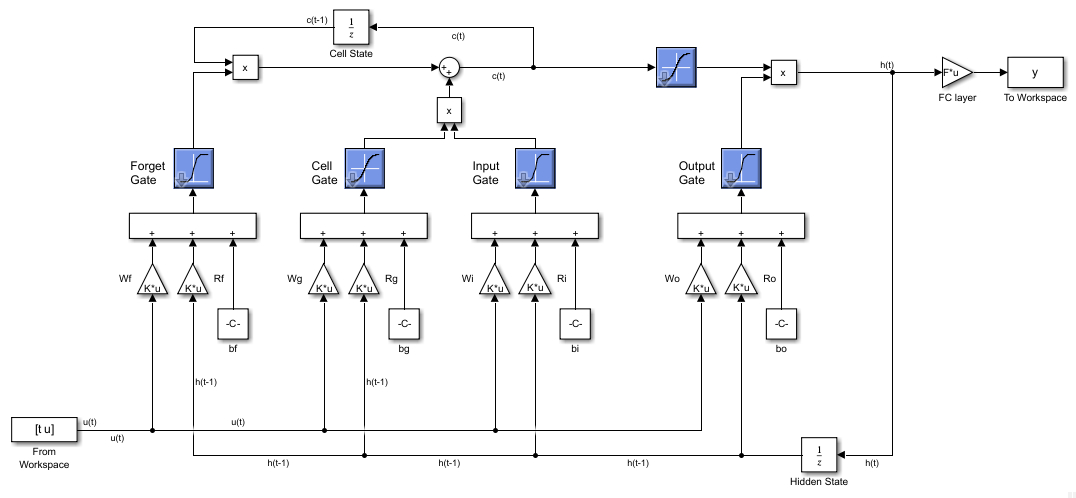

The input to the network is a vector of `Ni` components, each of which is an (independent) function of time, that is, a sequence of values. In what follows, the input sequence is indicated with $u\left(t\right)$, in line with normal notation used in the control community (the notation $x\left(t\right)$ is instead more commonly used to indicate network inputs in the machine learning community).

The LSTM layer uses `Nn` neurons (units). Each LSTM unit is associated with two states, a cell state, and a hidden state. The updates to both states are regulated by four *gates* (named *input*, *forget*, *cell candidate* and *output* gates, respectively) which are `sigmoid` or `tansig` activated functions of all inputs and states. Specifically, the cell candidate gate is activated by a `tansig` (hyperbolic tangent) function, the other gates are activated by a sigmoid function. Both the cell and hidden state feed back into themselves using an "inner" and "outer" feedback loop, with a structure that is reminiscent of - though more interconnected than - a cascade control system.

The $h\left(t\right)$ vector, which contains the hidden states of all the units as components, is also the output of the LSTM layer. The LSTM layer is followed by a fully connected linear layer (for this example being just the matrix gain $F$), which takes the vector of `Nn` hidden states $h\left(t\right)$ as input and outputs a vector of `No` components.

Note that the three sigmoid-shaped and the two tansig-shaped activation functions not only allow nonlinear function approximations, especially when multiple LSTM layers are placed in series, but also prevent the magnitude of the signals flowing in the loop to reach one. This allows information to persist while at the same time preventing loop signals from growing indefinitely and backpropagation gradients to vanish.

## Set Parameters and Simulate the Model

To simulate the model, first, define the number of neurons, as well as the number of inputs and outputs of the network. Define a network with three inputs, four neurons in the LSTM layer, and two outputs (to change the dimension of any of these signals, modify the following line).

Nn = 3; Ni = 4; No = 2;

To ensure reproducibility, fix the seed of the random generator.

rng(0)

Define random initial states.

h0 = rand(Nn,1);
c0 = rand(Nn,1);

The weight matrix $W$ connects each network input to each of the four gates of each unit. Specifically, $W=\left\lbrack W_i \;;W_f \;;\;W_g \;;\;W_o \right\rbrack$, where the subscripts, $i$,$f$,$\;g$, and $o$ denote the input, forget, cell candidate and output gates, respectively (and the semicolon indicates vertical stacking). 

Define $W$ as a random array.

W = rand(4*Nn,Ni); 

The weight matrix $R$ connects the hidden state of each unit at the previous time step, $h\left(t-1\right)$, to each of the four gates of each unit. Specifically, $R=\left\lbrack R_i \;;R_f \;;\;R_g \;;\;R_o \right\rbrack$.  

Define $R$ as a random array.

R = rand(4*Nn,Nn);

The bias vector $b$ contains the biases for each of the four gates, for each unit. Specifically, $b=\left\lbrack b_i \;;b_f \;;\;b_g \;;\;b_o \right\rbrack$. 

Define $b$ as a random array.

b = rand(4*Nn,1);

Finally define the fully connected layer matrix $F$, which produces the network outputs from $h\left(t\right)$, as a random array with no bias.

F = rand(No,Nn);

Define a time vector, `t`, with a sampling time `0.1` seconds, and random input sequence, `u`.

Ts = 0.1;
t = (0:Ts:50*Ts)';
u = randn(length(t),Ni);

The **From Workspace** block supplies the input sequence to the model, and the **To Workspace** block returns the output sequence in the workspace variable `y`. 

Simulate the model and display the first 5 samples of the output.

sim("lstm_sim");
y(1:5,:)'

ans =     0.5624    0.4918    0.5669    0.1661    0.0300
    1.3426    1.1631    1.3554    0.3430    0.0593


## LSTM Layer: Deep Learning Toolbox™

In this section, use the Deep Learning Toolbox to define and simulate the exact same network that you have previously defined and simulated with Simulink.

First, define the network as an array of layer objects. Use a regression layer as a final output layer (this instructs the training algorithm to compute the half-mean-squared-error loss for regression).

layers = [
   sequenceInputLayer(Ni)
   lstmLayer(Nn)
   fullyConnectedLayer(No)
   regressionLayer
];

Set the LSTM layer weights.

layers(2).InputWeights = W;
layers(2).RecurrentWeights = R;
layers(2).Bias = b;

Set the  LSTM layer states.

layers(2).HiddenState = h0;
layers(2).CellState = c0;

Set the weights of the fully connected layer (without loss of generality, keep the bias to zero).

layers(3).Weights = F;
layers(3).Bias = zeros(No,1);

Assemble layers into a series network object (this is necessary for training or prediction).

snet = assembleNetwork(layers);  

Calculate the network output when given `u` as input (the second input argument of `predict` must have time as a second - that is horizontal - dimension, so it is `u'` instead of `u`).

z = predict(snet,u');

Display the first five samples of `z`.

z(:,1:5)

ans = 2×5 single matrix
    0.5624    0.4918    0.5669    0.1661    0.0300
    1.3426    1.1631    1.3554    0.3430    0.0593


Display the norm of the difference between `z` and the output of the previous Simulink simulation, `y`.

norm(z'-y)

ans = single
5.8006e-07

The numerical difference is caused by the fact that while the Simulink model operates using the `double` format, the network operates using the `single` format. Apart from that, the result confirms that the two different representations of the LSTM are identical. 

## Connecting Multiple LSTM Layers in Series

After the first layer, you can connect another LSTM layer (indeed any number of LSTM layers in series) instead of the gain matrix $F$. It is well known that, loosely speaking, multiple nonlinear layers help to approximate efficiently (that is with exponentially less neurons) many "compositional" functions. For more information see [Chapter 6, Deep Learning](https://www.deeplearningbook.org/contents/mlp.html).

Note however that the number of parameters of an LSTM layer scales quadratically with the number of units (see the $R$ matrix) and linearly with the number of inputs (see the $W$ matrix), leading to a considerable growth in the number of total weights when connecting multiple LSTM layers in series. For example, suppose you are connecting two LSTM layers in series, and that both layers have 100 units. This implies that the $R$ matrices of both layers have 40000 elements. Additionally, since the number of inputs of the second layer must also be 100, the second layer has a $W$ matrix of 40000 elements, leading already to a total of 120000 elements even without considering the biases or the $W$ matrix of the first layer.

# How Well Can LSTMs Approximate Linear Dynamical Systems?

Attempting to answer this question sheds some light on the general approximation capabilities of LSTMs, and on the class of systems for which using an LSTM for system identification can potentially make some sense. Comparing the solution provided by a training algorithm to a solution that is manually calculated from the true system matrices also provides interesting insights.

## Define and Simulate Linear System

First, define a sample time and a linear discrete-time system. 

Create the system in zero-pole-gain form, convert to discrete time, and then convert to state space form.

Ts = 0.01;
sys = ss(c2d(zpk(-4,[-9+5i;-9-5i;-2+50i;-2-50i],5e5),Ts)); % for a general case: sys = drss(4,3,2,1); sys.Ts=Ts;

This system is the one used in the example [Use LSTM Network for Linear System Identification](https://www.mathworks.com/help/ident/ug/use-lstm-for-linear-system-identification.html). It is a fourth-order system, with a relative degree equal to three (in continuous time), which exhibits mixed fast and slow dynamics with moderate damping. These characteristics pose a challenge to any nonlinear structure that you use for system identification, as such structure must be able to capture both the fast and the slow dynamics before the response fades out.

In what follows $A$, $B$, $C$, and $D$ are the state space matrices and $x\left(t\right)$ is the state of the discrete-time system. For more information on how to handle linear time-invariant systems in MATLAB, see [Linear (LTI) Models](https://www.mathworks.com/help/control/getstart/linear-lti-models.html).

Display the system static gain (the $D$ matrix) and its steady state gain (which is, for discrete time systems, ${C\left(I-A\right)}^{-1} B+D$).

sys.D

ans = 0

dcgain(sys)

ans = 7.5351

Display the system in zero-pole-gain form.

zpk(sys)

ans =
 
     0.078673 (z+3.517) (z-0.9608) (z+0.2599)
  ----------------------------------------------
  (z^2 - 1.826z + 0.8353) (z^2 - 1.72z + 0.9608)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


Note that all zeros are on the real axis.

To simulate the linear system, define a time vector and a random input sequence.

t = 0:Ts:50*Ts;
u = randn(length(t),size(sys.B,2));

Without loss of generality, set the initial state for the linear system to zero.

x0 = zeros(size(sys.B,1),1);

Simulate the linear system using the [`lsim`](https://www.mathworks.com/help/ident/ref/lti.lsim.html) function. Transpose the response to obtain a row vector, and store it in the variable `y`.

y = lsim(sys,u,t,x0)';

## Define and Simulate LSTM with Calculated Weights

In this section, calculate a set of weights that approximate the linear system, and then simulate the network with these weights to verify the quality of the approximation.

Define the number of units (neurons), inputs and outputs for the network. Use as many neurons as the number of system states *plus the number of inputs*, and (obviously) the same number of inputs and outputs of the system to be approximated.

Nn = size(sys.B,1) + size(sys.B,2); Ni = size(sys.B,2); No = size(sys.C,1);

Define the network as an array of layer objects.

layers = [
   sequenceInputLayer(Ni)
   lstmLayer(Nn)
   fullyConnectedLayer(No)
   regressionLayer
];

Define a scaling factor to scale the network operations in a neighborhood of zero, in which the hyperbolic tangent activation functions behave as linear (identity) functions. The network inputs are scaled down by this factor and the outputs are then scaled up.

scl = 1e-3;

Calculating the weight that best approximate the linear system relies on three main ideas.

First, silence both input and output gate so that they let everything pass through. Specifically, make sure that the output of the (sigmoid) activation functions for both the input and output gate is always one (or very close to it). This can be achieved by setting both $b_i$ and $b_o$ to a very large number, and the corresponding $W_i$, $W_o$, $R_i$ and $R_o$ matrices to zero. 

Second, use the forget gate to permanently disable the cell state ($c\left(t\right)==0$). Specifically, make sure that the output of the (sigmoid) activation function for the forget gate is always zero (or very close to it). This can be achieved by setting $b_f$ to a very large *negative* number and the corresponding $W_f$ and $R_f$ matrices to zero.

Third, set the hidden state so that it contains two parts $h_1 \left(t\right)$ and $h_2 \left(t\right)$, and that at the next time step $h_1 \left(t\right)$ is updated with $Ah_1 \left(t-1\right)+\textrm{Bu}\left(t\right)$, while $h_2 \left(t\right)$ just carries the input $u\left(t\right)$ directly to the output $F$ matrix (assuming$\;h\left(t\right)\ll 1$ and therefore $\textrm{tansig}\left(h\left(t\right)\right)\simeq h\left(t\right)$). 

This last goal can be achieved by setting $R_g =A_{\textrm{nn}} =\left\lbrack \begin{array}{cc}
A & 0\\
0 & 0
\end{array}\right\rbrack$, $W_g =B_{\textrm{nn}\;} =\left\lbrack \begin{array}{c}
B\\
I
\end{array}\right\rbrack$, and $b_g =0$, and can be visualized as follows:

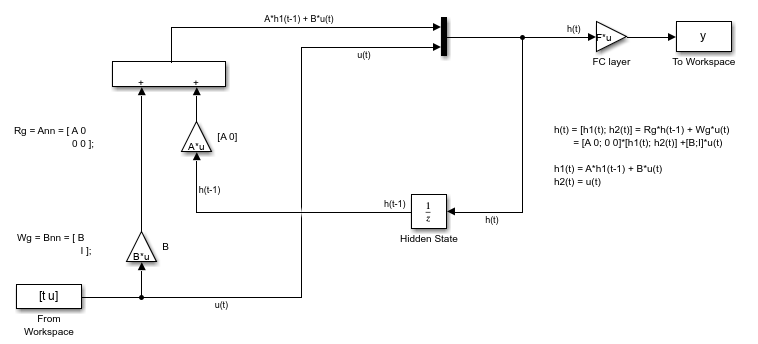

Assuming $h_1 \left(t-1\right)\approx x\left(t\right)$, this would result in the dynamics $x\left(t+1\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)$ which is the dynamics of the system to be approximated.

Define the LSTM weight matrices as indicated.

W = scl*[zeros(Nn,Ni); zeros(Nn,Ni); [sys.B; eye(Ni)]; zeros(Nn,Ni)];
R = [zeros(Nn); zeros(Nn); blkdiag(sys.A,zeros(Ni)); zeros(Nn)];
b = [1e2*ones(Nn,1); -1e2*ones(Nn,1); zeros(Nn,1); 1e2*ones(Nn,1)];

As for the output equation, $y\left(t\right)=Fh\left(t\right)=F\left\lbrack \begin{array}{c}
h_1 \left(t\right)\\
h_2 \left(t\right)
\end{array}\right\rbrack =F\left\lbrack \begin{array}{c}
Ah_1 \left(t-1\right)+\textrm{Bu}\left(t\right)\\
u\left(t\right)
\end{array}\right\rbrack =F\left\lbrack \begin{array}{c}
\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\\
u\left(t\right)
\end{array}\right\rbrack$. 

Therefore, assuming that $A$ is invertible (which for a discrete time system is reasonable) and choosing $F=\left\lbrack \begin{array}{cc}
CA^{-1}  & D-CA^{-1} B
\end{array}\right\rbrack$ results in:


$$y\left(t\right)=Fh\left(t\right)=\left\lbrack \begin{array}{cc}
CA^{-1}  & D-CA^{-1} B
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\\
u\left(t\right)
\end{array}\right\rbrack =CA^{-1} \textrm{Ax}\left(t\right)+CA^{-1} \textrm{Bu}\left(t\right)+\textrm{Du}\left(t\right)-CA^{-1} \textrm{Bu}\left(t\right)=\textrm{Cx}\left(t\right)+\textrm{Du}\left(t\right)$$


which is the output of the system to be approximated. 

Define the fully connected layer weight matrix as indicated.

F = [sys.C/sys.A sys.D-sys.C*pinv(sys.A)*sys.B]/scl;

Set the LSTM weight matrices.

layers(2).InputWeights = W;
layers(2).RecurrentWeights = R;
layers(2).Bias = b;

Set the LSTM states. Since the initial state of `sys` is assumed to be zero, set the LSTM state vectors to zero as well.

layers(2).HiddenState = zeros(Nn,1);
layers(2).CellState = zeros(Nn,1);

Set the weight matrix of the fully connected layer.

layers(3).Weights = F;
layers(3).Bias = zeros(No,1);

Assemble layers into a series network object.

snet = assembleNetwork(layers);

Calculate the network output sequence, using the same input sequence used to simulate the linear system.

z = predict(snet,u');

## Compare outputs

To compare the outputs, plot `y` and `z`.

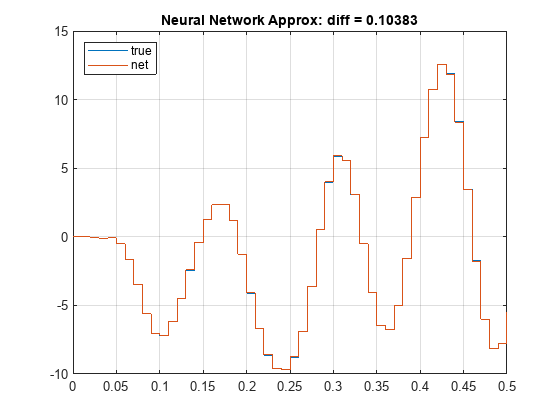

stairs(t',[y' z']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(y-z)) ])
grid

Despite the unavoidable approximation errors caused by the fact that the hyperbolic tangent functions in the LSTM deviate from linearity for higher input magnitudes, and (in very minor part) by the fact that the output of the sigmoid functions are never exactly zero or one, the LSTM still provides a very good approximation of the linear system.

# Train the LSTM to Approximate the Linear Systems

In reality, in a system identification problem, you only have access to the input and output signals of an unknown system, and you don't have any system representation (much less the $A$, $B$, $C$, and $D$ matrices of the linearized system) that you can leverage to set the weights of the LSTM network. Therefore, you have to estimate a sufficient number of neurons (you might or might not have an idea about the dimension of the state space of the system that generated the signals), start with random weight matrices, and rely on the training algorithm to find the best weight matrices that hopefully enable the LSTM to reproduce the validation output signal from the validation input one.

This problem is discussed in more detail in the example [Use LSTM Network for Linear System Identification](https://www.mathworks.com/help/ident/ug/use-lstm-for-linear-system-identification.html). However, given the fixed structure used in the previous section (a single LSTM layer with as many neurons as the number of states plus the number of inputs followed by a fully connected layer), it is of interest to find out if the training algorithm, starting from random initial weights, can find a solution which is close enough to the one calculated from the true system matrices.

A related question is what happens if the training algorithm is started directly from the calculated weights. In this case how much would the solution deviate (if at all) from the one shown in the previous section?

The following sections answer both questions.

## Define Training Input and Output Sequences

Define a time vector and a random input signal for training. For the training data, use more points than you used to compare outputs in the previous section.

ttr = 0:Ts:1e3*Ts;
utr = randn(length(ttr),Ni);

Without loss of generality, set the initial state for the linear system to zero.

x0 = zeros(size(sys.B,1),1);

Simulate the linear system using the [`lsim`](https://www.mathworks.com/help/ident/ref/lti.lsim.html) function, storing the response in the workspace variable `ytr`.

ytr = lsim(sys,utr,ttr,x0)';

## Define Network Training Options

For this example, use the Adam (name derived by adaptive momentum) algorithm with an initial learning rate of 0.0001. Set the learning rate schedule so that it drops to 99% every 100 steps. Set the gradient truncation threshold to 1 and use 10000 epochs used to train the network. Use the `Verbose` option to display the training progress (once every 500 steps) at the command line. 

opts = trainingOptions("adam",...
    InitialLearnRate=0.0001,...
    LearnRateSchedule="piecewise",...
    LearnRateDropPeriod=100,...
    Plots="none",...
    Verbose=true, ...
    VerboseFrequency=500, ...
    LearnRateDropFactor=0.99,...
    GradientThreshold=1,...
    MaxEpochs=10e3);

## Train the Network

To train the network, starting from the previously calculated weights, use `trainNetwork`. Transpose the input sequence so that time is along the second dimension. 

snet = trainNetwork(utr',ytr,layers,opts);  % otherwise: snet = assembleNetwork(layers); 

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         0.05 |      1.2e-03 |      1.0000e-04 |
|     500 |         500 |       00:00:02 |         1.22 |          0.7 |      9.6060e-05 |
|    1000 |        1000 |       00:00:05 |         0.65 |          0.2 |      9.1352e-05 |
|    1500 |        1500 |       00:00:07 |         0.56 |          0.2 |      8.6875e-05 |
|    2000 |        2000 |       00:00:09 |         0.60 |          0.2 |      8.2617e-05 |
|    2500 |        2500 |       00:00:11 |         0.55 |          0.2 |      7.8568e-05 |
|    3000 |        3000 |       00:00:14 |         0.44 |      9.7

The output `snet` is the trained network, returned as a `SeriesNetwork` object.

You can see that the minimum value of `Mini-batch` `RMSE` and `Mini-batch` `Loss` occur at the initial starting point. Both these measures increase as the algorithm moves away from the starting point and explores the optimization space looking for a better solution. After 10000 epochs the final loss value is still an order of magnitude higher than the initial one.

Note that only by using the very small learning rate of 1e-4 and increasing the number of epochs to 1e4 does lead to final weights that have a performance comparable to the original ones, on the training data set. Larger learning rates lead to worse results. This suggests that the initial point (featuring the calculated weights) lies in a very narrow attraction basin.

## Display the Weights Difference

It is interesting to display the difference between the final weights found by the algorithm and the optimal weights set manually in the previous section.

Original input weights for the input and forget gates:

W(1:2*Nn,:)'

ans =      0     0     0     0     0     0     0     0     0     0


Final input weights for the input and forget gates:

snet.Layers(2).InputWeights(1:2*Nn,:)' % 

ans = 1×10 single row vector
     0     0     0     0     0     0     0     0     0     0


Original input weights for the cell and output gates:

W(2*Nn+1:4*Nn,:)'

ans = 1.0e-03 *

         0    0.3104         0    0.5201    1.0000         0         0         0         0         0


Final input weights for the cell and output gates:

snet.Layers(2).InputWeights(2*Nn+1:4*Nn,:)'

ans = 1×10 single row vector
1.0e-03 *

   -0.1020    0.5005   -0.0107    0.6556    0.7104         0         0         0         0         0


The training algorithm changed only the weights corresponding to the $B$ matrix.

Original recurrent weights for the input and forget gates:

R(1:2*Nn,:)'

ans =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Final recurrent weights for the input and forget gates:

snet.Layers(2).RecurrentWeights(1:2*Nn,:)'

ans = 5×10 single matrix
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Original recurrent weights for the cell and output gates:

R(2*Nn+1:4*Nn,:)'

ans =     0.9128   -0.0021         0         0         0         0         0         0         0         0
    1.0000    0.9128         0         0         0         0         0         0         0         0
         0   -0.3945    0.8602   -0.2208         0         0         0         0         0         0
         0    2.5522    1.0000    0.8602         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0


Final recurrent weights for the cell and output gates:

snet.Layers(2).RecurrentWeights(2*Nn+1:4*Nn,:)'

ans = 5×10 single matrix
    0.8945   -0.0060   -0.0022   -0.0030    0.1176         0         0         0         0         0
    0.8428    0.9120   -0.0014   -0.0131   -0.0033         0         0         0         0         0
    0.0103   -0.3742    0.8512   -0.1820    0.0114         0         0         0         0         0
   -0.0440    2.4780    0.9958    0.8697    0.0193         0         0         0         0         0
    0.0325   -0.0211    0.0095    0.0086    0.1978         0         0         0         0         0


Similarly, the training algorithm changed only the weights corresponding to the $A$ matrix (and only slightly so). 

Original bias weights for the input and forget gates:

b(1:2*Nn,:)'

ans =    100   100   100   100   100  -100  -100  -100  -100  -100


Final bias weights for the input and forget gates:

snet.Layers(2).Bias(1:2*Nn,:)'

ans = 1×10 single row vector
   100   100   100   100   100  -100  -100  -100  -100  -100


Original bias weights for the cell and output gates:

b(2*Nn+1:4*Nn,:)'

ans =      0     0     0     0     0   100   100   100   100   100


Final bias weights for the cell gate:

snet.Layers(2).Bias(2*Nn+1:3*Nn,:)'

ans = 1×5 single row vector
1.0e-03 *

    0.0465   -0.0299   -0.0120    0.0029   -0.1981


Final bias weights for the output gates:

snet.Layers(2).Bias(3*Nn+1:4*Nn,:)'

ans = 1×5 single row vector
   100   100   100   100   100


Only the biases corresponding to the cell candidate gate, which is the ones that was used to build the signal $\textrm{Ah}\left(t-1\right)+\textrm{Bu}\left(t\right)$ (and to carry the input over to the fully connected layer), have a very small deviation from zero.

Display the starting and final weights of the fully connected layer:

F

F =   325.4911  -78.8823   18.4092  212.6357  -86.0996


snet.Layers(3).Weights

ans = 1×5 single row vector
  325.4088  -78.9724   18.4029  212.4181  -86.1198


Display the final bias of the fully connected layer (the initial one being zero):

snet.Layers(3).Bias

ans = single
-1.3186e-04

The weights of the final fully connected layer have changed a little, and their biases also have a very small deviation from zero.

## Extract Linear System from the Network Weights

Since the small deviations in the bias vectors are negligible, the final network weights still represent a linear system. To better characterize this system, and see how it differs from the original one, obtain the system matrices.

Ann=snet.Layers(2).RecurrentWeights(2*Nn+1:3*Nn,:);
Bnn=snet.Layers(2).InputWeights(2*Nn+1:3*Nn,:)/scl;
Cnn=scl*snet.Layers(3).Weights*Ann;
Dnn=scl*snet.Layers(3).Weights*Bnn;

Display the $D$ matrix.

Dnn

Dnn = single
0.0052

The static gain matrix has increased a bit with respect to the one of the original linear system.

Group the matrices into a discrete state space object.

snn=ss(Ann,Bnn,Cnn,Dnn,Ts);

Display the steady state gain.

dcgain(snn)

ans = 8.3344

The steady state gain has also increased with respect to the one of the original linear system. The increase is much larger than the one due to the $D$ matrix, and it is mostly due to the increase in the term ${C_{\textrm{nn}} \left(I-A_{\textrm{nn}} \right)}^{-1} B_{\textrm{nn}}$,  with respect to ${C\left(I-A\right)}^{-1} B$, which is in turn caused by the slight changes in the system matrices.

Display the system in zero-pole-gain form.

zpk(snn)

ans =
 
  0.0051693 (z-0.9464) (z-0.1091) (z-1.201e-07) (z^2 + 9.632z + 67.54)
  --------------------------------------------------------------------
       (z-0.1826) (z^2 - 1.822z + 0.8337) (z^2 - 1.721z + 0.9611)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


As expected, this is a fifth-order system with an additional (with respect to the original linear system) zero and pole that almost cancel each other (`0.1091` and `0.1826`, respectively). Since the $D$ matrix (which is also the limit of the transfer function for $z\longrightarrow \infty$) is very small but nonzero, the system must have as many zeros as there are poles. Indeed, there is another additional (still with respect to the original linear system) zero very close to the origin (`1.201e-7`). The poles are almost unchanged, as is the dominant real zero (`0.9464`). However, the other two zeros which used to lie on the real axis have now become complex ones.

## Compare Outputs on Validation Data

To compare the outputs of the trained network to the ones linear system on a different dataset than the training one, evaluate the response of the trained network to the previously defined input sequence `u`.

z = predict(snet,u');

To compare the outputs, plot the linear system response `y` and the network response `z`.

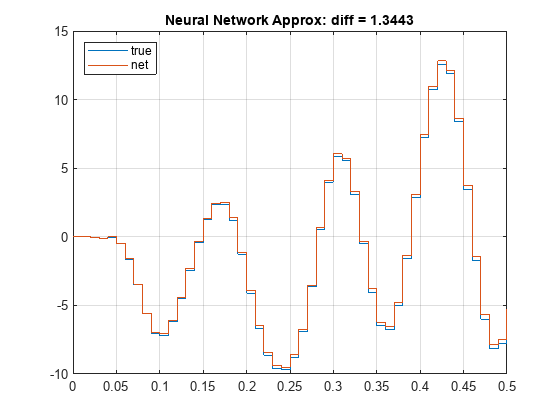

stairs(t',[y' z']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(y-z)) ])
grid

As expected, the neural network that was trained starting from the calculated weights is not able to perform as well as the initial (untrained) network that featured the calculated weights. However, since the final weight do not deviate a lot from the initial ones (due to the very small learning rate used for training) the performance is still acceptable.

To test the network linearity, evaluate the response of the trained network to the input sequence 3`*u`.

z3 = predict(snet,3*u');

To compare the outputs, plot the linear system response `3*y` and the network response `z3`.

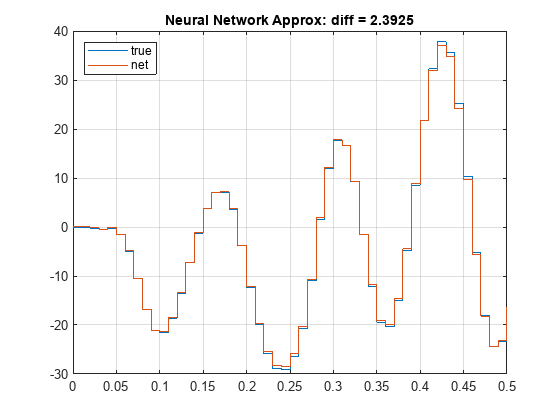

stairs(t',[3*y' z3']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(3*y-z3)) ])
grid

The error increased only slightly more than threefold, confirming that with these weights, when the input is within the range shown in the picture, the network substantially behaves linearly (even though slight deviations from linearity, probably due to the `tansig` functions, seem to appear when the input magnitude is greater than 20). 

## Using Only as Many Neurons as the Number of States

It is natural to consider the question of what happens if one chose an LSTM with many neurons as the number of system states, (as opposed to the number of system states plus the number of inputs). In this case, (as a previous version of this example showed), a direct path from the input to the output that is independent from $h\left(t-1\right)$ does not exist, and the output gain matrix $F$ must balance between the different output components $\textrm{Ch}\left(t-1\right)$ and $\textrm{Du}\left(t\right)$.

Here, selecting $F=CA^{-1}$ prioritizes the state-to-output path at the expense of the input-to-output one, and results in static gain matrix $D_{\textrm{LSTM}} =CA^{-1} B$, which is generally different from $D$. Therefore, with this weights selection, the more the $D$ matrix in the original linear system deviates from $CA^{-1} B$, the worst its LSTM approximation is bounded to be. 

On the other hand, for some linear systems, like the one in this example, the approximation performance is still good despite the presence of such static gain matrix. Furthermore, when the network is trained starting from these initial calculated weights (and provided that a very small learning rate is used), the training algorithm might be able to change the weights to obtain a better trade-off between the state-to-output path and the input-to-output one. In other words, the training algorithm might be able to find some LSTM weights and an $F\not= CA^{-1}$ (and therefore a static gain $D_{\textrm{LSTM}} \not= CA^{-1} B$) that overall result in an approximation of the original system which is marginally better than the one represented by the initial, calculated, weights.

## Set the Network Weights Randomly

To see if the training algorithm, when starting from random initial weights, can find a set of weights that yields an acceptable approximation of the true linear system, set the initial matrices randomly.

Set the LSTM weight matrices.

layers(2).InputWeights = rand(4*Nn,Ni);
layers(2).RecurrentWeights = rand(4*Nn,Nn);
layers(2).Bias = rand(4*Nn,1);

Set the LSTM initial states to zero.

layers(2).HiddenState = zeros(Nn,1);
layers(2).CellState = zeros(Nn,1);

Set the weight matrix of the fully connected layer.

layers(3).Weights = rand(No,Nn);
layers(3).Bias = zeros(No,1);

## Define Network Training Options

Since you are starting from random weight, you might want to change some training options such as the learning rate, the number of epochs, and the display frequency. For this example, use an initial learning rate of 0.04, and train the network for 10000 epochs. Display the training progress on the command line once every 500 steps. 

opts = trainingOptions("adam",...
    InitialLearnRate=0.04,...
    LearnRateSchedule="piecewise",...
    LearnRateDropPeriod=100,...
    Plots="none",...
    Verbose=true, ...
    VerboseFrequency=500, ...
    LearnRateDropFactor=0.98,...
    GradientThreshold=1,...
    MaxEpochs=10000);

## Train the Network

To train the network, use `trainNetwork`. Use the same training dataset as before.

snet = trainNetwork(utr',ytr,layers,opts);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         7.79 |         30.3 |          0.0400 |
|     500 |         500 |       00:00:02 |         1.58 |          1.3 |          0.0369 |
|    1000 |        1000 |       00:00:04 |         1.24 |          0.8 |          0.0333 |
|    1500 |        1500 |       00:00:07 |         1.03 |          0.5 |          0.0301 |
|    2000 |        2000 |       00:00:09 |         0.99 |          0.5 |          0.0272 |
|    2500 |        2500 |       00:00:11 |         0.85 |          0.4 |          0.0246 |
|    3000 |        3000 |       00:00:14 |         0.86 |         

Both the `Mini-batch` `RMSE` and the `Mini-batch` `Loss` are very large at the beginning, but the training algorithm is able so steadily decrease them. After 10000 epochs both measures approach values that are comparable to the ones seen in the previous training run.

It is important to highlight (and easy to verify) that the solution is extremely dependent on both the initial starting point and the various algorithm hyperparameters. For example, changing the third significant digit of the learning rate drop factor can lead to substantially different results.

## Display Weights Difference

Display the difference between the final weights found by the algorithm and the weights calculated from the original system matrices in the previous section.

(snet.Layers(2).InputWeights-W)'

ans = 1×20 single row vector
   -0.0919    0.0588    0.1127    0.0944   -0.0237    0.0214    0.0716    0.0877    0.3588   -0.1349   -0.0901    0.0650   -0.1366    0.1223    0.0975   -0.1926   -0.2249   -0.1913   -0.0474   -0.1319


(snet.Layers(2).RecurrentWeights-R)'

ans = 5×20 single matrix
   -0.2340   -1.3237   -2.3965   -1.9736   -0.4476   -0.6110   -0.1305   -0.8528    0.5928    0.6990    0.0971    1.0160    1.4263    0.9799   -0.4698    0.2391    3.2398   -0.6364   -0.4315   -0.1287
   -0.6028    0.2485   -0.4050   -2.5686   -0.6631   -0.4608    0.2269   -0.2467   -0.3138    0.3184   -0.7738   -1.0656    0.2130   -0.8770    0.0679    0.0896   -1.3545   -0.6211    0.4396   -0.1194
    1.8724    0.7087    1.6551    1.1433    0.7495   -1.4890   -0.4155    0.2958   -0.3544    0.2765   -0.7758    0.7803    0.0319    1.0433   -1.1490    0.3484   -0.2012   -1.3074    1.9167    0.6638
   -0.3808    0.0913    0.7406   -1.0760   -1.0345   -0.3555   -0.6741   -0.2733    1.9615    0.4667    0.3650   -2.2391   -1.1952    0.0672    0.0678    0.4840   -0.0827    0.6064   -0.5449    1.7716
    1.9400    1.0924    1.0276   -0.4835    1.5266    1.2978   -0.3887   -1.2691   -0.9283    0.4659    2.7469    0.6827    1.1388    1.4984    0.4022    0.1439    0.7708 

(snet.Layers(2).Bias-b)'

ans = 1×20 single row vector
  -99.1886  -99.2191  -98.6469 -100.0967  -98.5145  100.8852  101.8044  100.9412  101.3732  101.0161    0.8948   -0.0107   -0.7022    0.6627   -0.6085  -97.9741  -97.0490  -97.6215  -98.7103  -99.1310


snet.Layers(3).Weights-F

ans = 1×5 single row vector
 -324.5878  106.6501  -10.6260 -201.8867   75.4732


snet.Layers(3).Bias

ans = single
-3.3492

The solution found by algorithm seems to be quite different from the one found by manually setting the calculated parameters. In particular, it is not clear the extent to which the system represented by these final weights is even linear.

## Compare Outputs

To compare the trained network to the linear system on a different dataset than the training one, evaluate the response of the trained network to the same validation input sequence `u`.

z = predict(snet,u');

To compare the outputs, plot the linear system response `y` and the network response `z`.

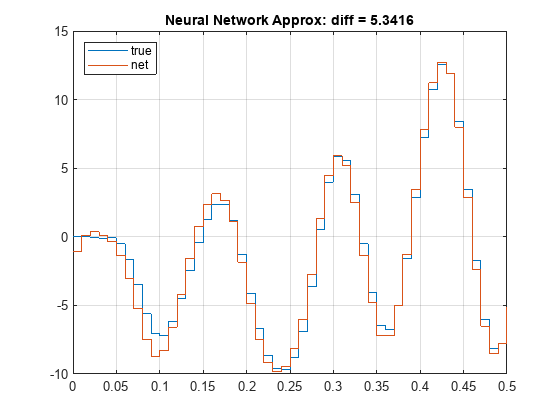

stairs(t',[y' z']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(y-z)) ])
grid

Perhaps surprisingly, while performance is not nearly as good as in the original network with fixed parameters, it is perhaps still acceptable.

To test the network linearity, evaluate the response of the trained network to the input sequence 3`*u`.

z3 = predict(snet,3*u');

To compare the outputs, plot the linear system response `3*y` and the network response `z3`.

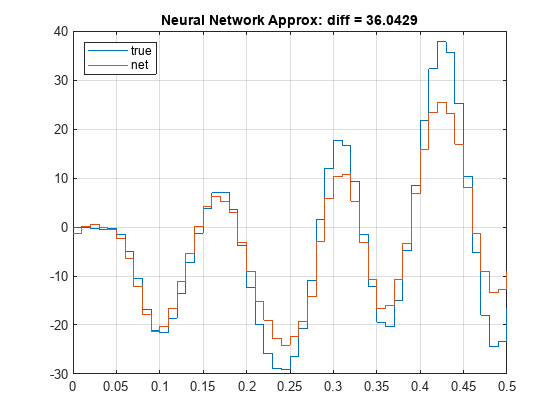

stairs(t',[3*y' z3']);
legend("true","net",Location="northwest");
title(['Neural Network Approx: diff = ' num2str(norm(3*y-z3)) ])
grid

While the response might still be acceptable in the input range from -20 to 20, there is a substantial deviation from linearity for larger inputs. In other words, with these weights, and with inputs magnitudes larger than 20, the network does not behave as a linear system.

## Conclusions

An LSTM layer is a nonlinear dynamical system in which each unit (neuron) is associated to two states, called cell and hidden state. These states feed back into themselves using an inner and an outer feedback loop, somewhat (superficially) similarly to a cascade control system. It is possible that such structure could make it easier to approximate systems having both slow (long term) and fast (short term) dynamics. Two hyperbolic tangent functions in these loops prevent signals from growing indefinitely. The loop signals are also modulated by four "gates". 

In the first part of this example, a Simulink representation of the layer was illustrated, and shown to be identical to a network build using layer object from the Deep Learning Toolbox.

The second part of the example shows that given any discrete-time linear dynamical system in which $A$ is invertible, it is possible to find a set of LSTM weights that approximates it to any degree of accuracy, within a reasonable input range. This solution involves disabling the cell states and using as many hidden states as the number of states plus the number of inputs of the original system. Here, the input, output and forget gates are disabled and the cell gate is used to both reproduce the system dynamics and open a channel from the input to the output. 

This solution was explained theoretically and practically illustrated for a given fourth-order discrete-time linear system.

Training the network from this initial set of weights shows that this solution has a very narrow attraction basin. Only using a very small learning rate the training algorithm is able to remain in the vicinity of the solution and produce a set of weights for which the network response still acceptably approximates the linear system.

In the final part of the example, the network was trained from random initial conditions, which is the typical case in system identification (where input and output data is typically all one has). In this case, the training algorithm ends up in a local minimum that is quite different from, and does not perform as well as, the solution calculated from the matrices of the original system.

Furthermore, for the considered one-layer network, the solution is also very dependent on the hyperparameters of the training algorithm. For example, a very minimal change in the learning rate drop factor causes the algorithm to find a different minimum.

It is important to note that networks with more LSTM neurons and more than one LSTM layer are indeed able to reliably find good approximations of linear systems even when starting from random initial weights. However, as discussed in an earlier section, such networks pay a price in terms of complexity because the number of parameters of an LSTM scales *quadratically* with the number of units, easily leading to networks having hundreds of thousands of parameters. In turn, this proliferation of parameters leads not only to longer training times, but also to other issues such as the need to properly set all the network internal states. Such issues are very clearly illustrated in the example [Use LSTM Network for Linear System Identification](https://www.mathworks.com/help/ident/ug/use-lstm-for-linear-system-identification.html).

*G. Campa - 4-Apr-2023*